clear; clc; close all;
p = gcp('nocreate');
if ~isempty(p)
    delete(p);
end
warning('off','all');
rng(0, 'twister');

feature('DefaultCharacterSet','UTF-8');
trainingPlot.Language = "en";

%% 1. Configuration 

datasetRoot = fullfile(pwd, "recordings");   

fsTarget    = 8000;      % resample to 8 kHz
numMFCC     = 13;        % MFCC order
useDelta    = true;      % add delta & delta-delta

numMelBands = 40;        % log-mel bands for CNN
frameLen    = 256;       % STFT frame length
hopLen      = 128;       % STFT hop
maxTimeSec  = 1.0;       % pad/trim to 1 s

trainRatio  = 0.7;       % 70% train, 15% val, 15% test
valRatio    = 0.15;

snrLevels = [0 5 10 15 20]; % SNRs for robustness test (dB)

%% 2. Load dataset 
ads = audioDatastore(datasetRoot, ...          % create datastore that indexes all audio files
    "IncludeSubfolders", true, ...             % also search all subfolders under datasetRoot
    "FileExtensions", ".wav", ...              % only include .wav files
    "LabelSource", "none");                   % do not auto-generate labels (we set them manually)

numFiles = numel(ads.Files);                 % total number of audio files found

if numFiles == 0                           % sanity check: no files -> stop with error
    error("No wav files under %s", datasetRoot); % tell user that dataset folder is empty / wrong
end

% labels from filename first char
labels = cell(numFiles,1);                    % pre-allocate cell array for string labels

for i = 1:numFiles                              % loop over all files
    [~, name, ~] = fileparts(ads.Files{i});     % extract filename without path and extension
    digitChar = name(1);                        % assume first character is the digit label (0–9)
    if ~ismember(digitChar, '0123456789')       
        error("File '%s' does not start with digit 0-9.", name);  % throw descriptive error
    end
    labels{i} = digitChar;                       % store digit label as a char in the cell array
end

ads.Labels = categorical(labels);                % convert char labels to categorical class labels

fprintf("Loaded %d files.\n", numFiles);         % print total number of files

Loaded 3000 files.


disp("Label distribution:");                     % show how many samples per digit

Label distribution:


disp(countcats(ads.Labels));                     % count occurrences for each categorical label

   300
   300
   300
   300
   300
   300
   300
   300
   300
   300



%% 3. Train/val/test split 

[adsTrain, adsRest] = splitEachLabel(ads, trainRatio);        % split into training set and remaining data (val+test) with balanced labels
valPortion = valRatio / (1 - trainRatio);                     % convert global val ratio into ratio within the remaining portion
[adsVal, adsTest]  = splitEachLabel(adsRest, valPortion);     % split remaining data into validation and test sets (also label-balanced)

fprintf("Train: %d, Val: %d, Test: %d\n", ...                  % print number of files in each subset for sanity check
    numel(adsTrain.Files), numel(adsVal.Files), numel(adsTest.Files));

Train: 2100, Val: 450, Test: 450


%% 4. Baseline features: MFCC(+delta) for SVM 

fprintf("Extracting MFCC-based features (baseline)...\n");

Extracting MFCC-based features (baseline)...


[XTrain_mfcc, yTrain] = extractFrameFeatures(adsTrain, fsTarget, ...
    "mfcc", numMFCC, useDelta, [], frameLen, hopLen, maxTimeSec);

[XVal_mfcc,   yVal]   = extractFrameFeatures(adsVal, fsTarget, ...
    "mfcc", numMFCC, useDelta, [], frameLen, hopLen, maxTimeSec);

[XTest_mfcc,  yTest]  = extractFrameFeatures(adsTest, fsTarget, ...
    "mfcc", numMFCC, useDelta, [], frameLen, hopLen, maxTimeSec);

%% 5. Baseline model: SVM with small grid search 

params.kernelScaleList   = [0.5 1 2];                         % candidate values for RBF kernel scale
params.boxConstraintList = [0.5 1 2];                         % candidate values for SVM box constraint C

fprintf("Training baseline SVM (MFCC features)...\n");        

Training baseline SVM (MFCC features)...


[svmModel, svmCfg] = trainSVMWithValidation( ...              % train SVM on MFCC(+delta) features and select best hyper-parameters
    XTrain_mfcc, yTrain, params);

  ks=0.50, C=0.50 -> CV acc=0.288
  ks=0.50, C=1.00 -> CV acc=0.288
  ks=0.50, C=2.00 -> CV acc=0.218
  ks=1.00, C=0.50 -> CV acc=0.760
  ks=1.00, C=1.00 -> CV acc=0.758
  ks=1.00, C=2.00 -> CV acc=0.664
  ks=2.00, C=0.50 -> CV acc=0.929
  ks=2.00, C=1.00 -> CV acc=0.936
  ks=2.00, C=2.00 -> CV acc=0.942
Best CV acc = 0.942



fprintf("Best SVM: kernelScale=%.2f, C=%.2f\n", ...           % report chosen hyper-parameters from validation
    svmCfg.kernelScale, svmCfg.boxConstraint);

Best SVM: kernelScale=2.00, C=2.00



[~, accTrain_svm] = evaluateClassifier(svmModel, ...          % accuracy on training set (overfitting indicator)
    XTrain_mfcc, yTrain);
[~, accVal_svm]   = evaluateClassifier(svmModel, ...          % accuracy on validation set (model selection)
    XVal_mfcc,   yVal);
[yPred_svm, accTest_svm, confTest_svm] = evaluateClassifier( ...  % accuracy and confusion matrix on held-out test set
    svmModel, XTest_mfcc, yTest);

fprintf("Baseline SVM Acc: train=%.2f%%, val=%.2f%%, test=%.2f%%\n", ...  % summary of SVM performance
    accTrain_svm*100, accVal_svm*100, accTest_svm*100);

Baseline SVM Acc: train=99.95%, val=86.67%, test=57.33%


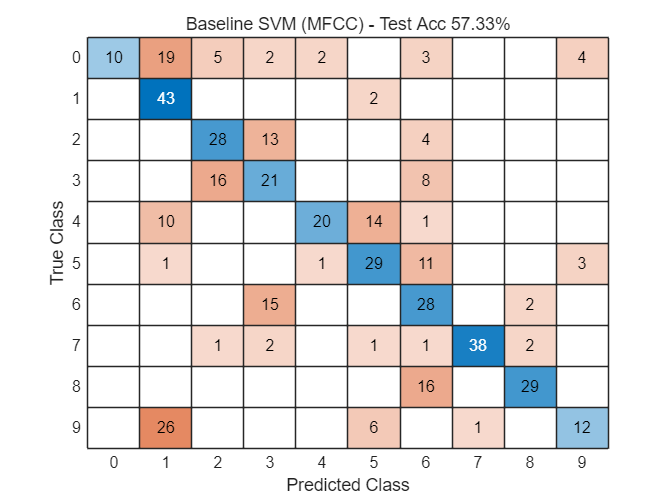


figure;
confusionchart(confTest_svm, categories(yTest));              % visualize per-class performance using confusion matrix
xlabel("Predicted Class");
ylabel("True Class");
title(sprintf("Baseline SVM (MFCC) - Test Acc %.2f%%", ...    % title includes overall test accuracy
    accTest_svm*100));

%% 6. CNN features: log-mel spectrogram "images"

fprintf("Extracting log-mel spectrograms for CNN...\n");

Extracting log-mel spectrograms for CNN...


[XTrain_cnn, yTrain_cnn] = extractSpectrogramSet(adsTrain, fsTarget, ...
    numMelBands, frameLen, hopLen, maxTimeSec, []);

[XVal_cnn,   yVal_cnn]   = extractSpectrogramSet(adsVal, fsTarget, ...
    numMelBands, frameLen, hopLen, maxTimeSec, []);

[XTest_cnn,  yTest_cnn]  = extractSpectrogramSet(adsTest, fsTarget, ...
    numMelBands, frameLen, hopLen, maxTimeSec, []);

inputSize = size(XTrain_cnn(:,:,:,1));  

%% 7. Define and train small CNN 

layers = buildCnnLayers(inputSize, numel(categories(yTrain_cnn)));  % create a small CNN architecture for log-mel inputs

miniBatchSize = 64;                                                 % number of samples per mini-batch
maxEpochs     = 20;                                                % maximum number of training epochs

opts = trainingOptions("adam", ...                                  % use Adam optimizer for training
    "MaxEpochs", maxEpochs, ...                                    % total number of epochs
    "MiniBatchSize", miniBatchSize, ...                              % mini-batch size
    "Shuffle", "every-epoch", ...                                   % shuffle training data at the start of each epoch
    "ValidationData", {XVal_cnn, yVal_cnn}, ...                      % validation set used to monitor generalisation
    "ValidationFrequency", 30, ...                                  % validate every 30 iterations
    "Verbose", true, ...                                            % print training progress to command window
    "Plots", "training-progress");                                 % show live training/validation curves

fprintf("Training CNN (log-mel)...\n");                             % message to indicate that CNN training starts

Training CNN (log-mel)...


在单 GPU 上训练。
正在初始化输入数据归一化。
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　轮　　｜　　迭代　　｜　　　　经过的时间　　　　　｜　　小批量准确度　　｜　　验证准确度　　｜　　小批量损失　　｜　　验证损失　　｜　　基础学习率　　｜
｜　　　　　｜　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　｜　　　　　　　　　｜　　　　　　　　　｜　　　　　　　　｜　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　　１　｜　　　　１　｜　　　　　００：００：００　｜　　　　４．６９％　｜　　１１．５６％　｜　　４．００７２　｜　３．１３４０　｜　　０．００１０　｜
｜　　　１　｜　　　３０　｜　　　　　００：００：０１　｜　　　２１．８８％　｜　　２２．２２％　｜　　２．２４００　｜　２．１８９４　｜　　０．００１０　｜
｜　　　２　｜　　　５０　｜　　　　　００：００：０１　｜　　　２５．００％　｜　　　　　　　　　｜　　２．０７９２　｜　　　　　　　　｜　　０．００１０　｜
｜　　　２　｜　　　６０　｜　　　　　００：００：０１　｜　　　２３．４４％　｜　　３２．６７％　｜　　１．９６１０　｜　１．８８５５　｜　　０．００１０　｜
｜　　　３　｜　　　９０　｜　　　　　００：００：０２　｜　　　５４．６９％　｜　　５６．８９％　｜　　１．３５７７　｜　１．３５７８　｜　　０．００１０　｜
｜　　　４　｜　　１００　｜　　　　　００：００：０２　｜　　　４０．６２％　｜　　　　　　　　　｜　　１．４４４１　｜　　　　　　　　｜　　０．００１０　｜
｜　　　４　｜　　１２０　｜　　　　　００：００：０２　｜　　　７０．３１％　｜　　６５．５６％　｜　　０．９５３９　｜　０．９５１６　｜　　０．００１０　｜
｜　　　５　｜　　１５０　｜　　　　　００：００：０３　｜　　　７０．３１％　｜　　７９．７８％　｜　　０．８１１５　｜　０．６４５０　｜　　０．００１０　｜
｜　　　６　｜　　１８０　｜

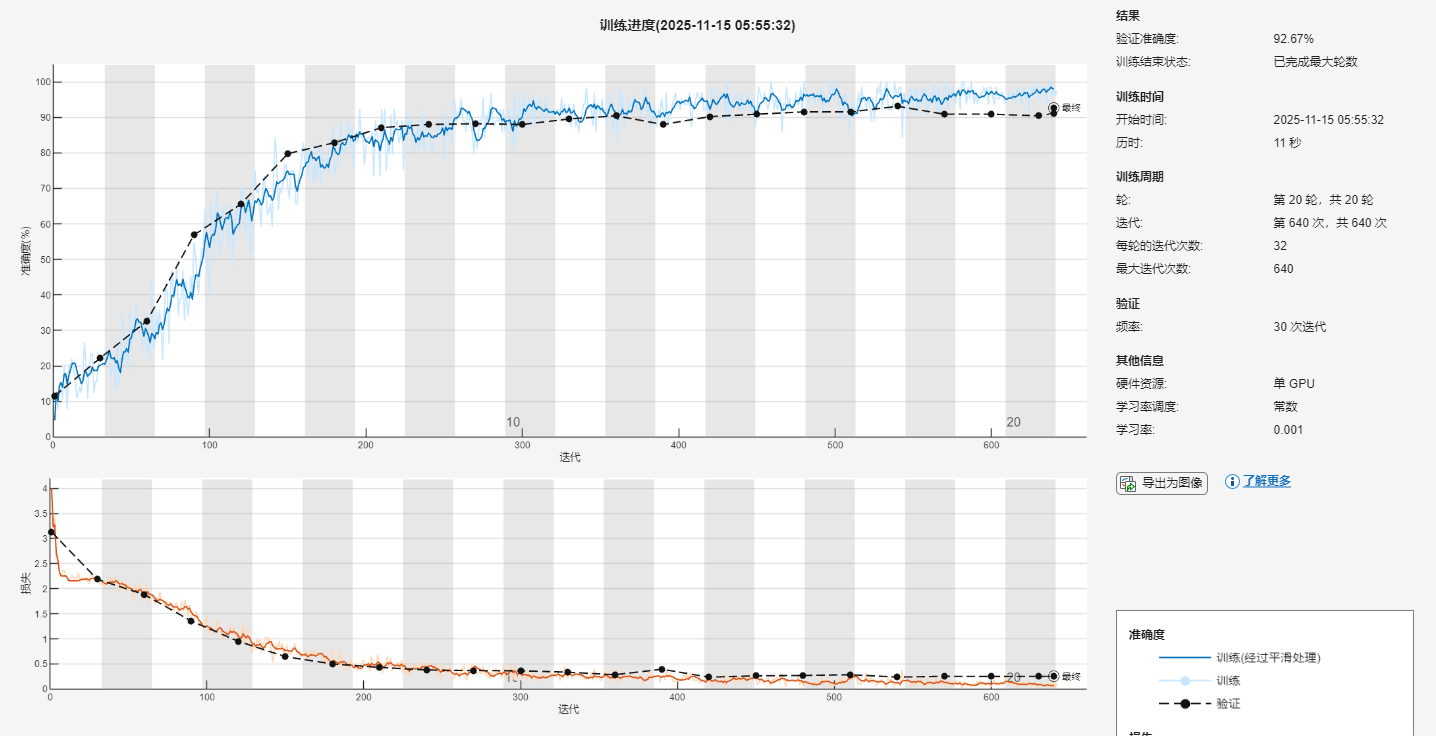

net = trainNetwork(XTrain_cnn, yTrain_cnn, layers, opts);           % train the CNN on log-mel spectrogram inputs

%% 8. Evaluate CNN on clean test set + latency 

% 8.1 accuracy
tStart = tic;                                                        % start timer for single forward pass
yPred_cnn_clean = classify(net, XTest_cnn);                          % classify all clean test samples with trained CNN
tElapsed = toc(tStart);                                              % total time for one pass over the test set

accTest_cnn = mean(yPred_cnn_clean == yTest_cnn);                    % overall test accuracy on clean data
fprintf("CNN Test Acc (clean): %.2f%%\n", accTest_cnn*100);          % print accuracy as percentage

CNN Test Acc (clean): 74.00%


fprintf("Single pass over %d test samples took %.4f s (%.4f s / sample)\n", ... % timing information
    numel(yTest_cnn), tElapsed, tElapsed/numel(yTest_cnn));

Single pass over 450 test samples took 0.0840 s (0.0002 s / sample)



% To obtain a more stable delay estimate, multiple repeated measurements are performed.
numRepeats = 20;                                                     % number of repeated timing runs
latArray = zeros(numRepeats,1);                                      % store latency of each run
for r = 1:numRepeats                                                 % repeat forward pass several times
    t0 = tic;                                                        % start timer for this run
    classify(net, XTest_cnn);                                       % run classification (results are ignored here)
    latArray(r) = toc(t0);                                           % store elapsed time for this run
end
avgLatencyPerSample = mean(latArray) / numel(yTest_cnn);            % average latency per sample over all runs
fprintf("Average CNN latency per sample over %d runs: %.4f ms\n", ...% print mean latency in milliseconds
    numRepeats, avgLatencyPerSample*1000);

Average CNN latency per sample over 20 runs: 0.0282 ms


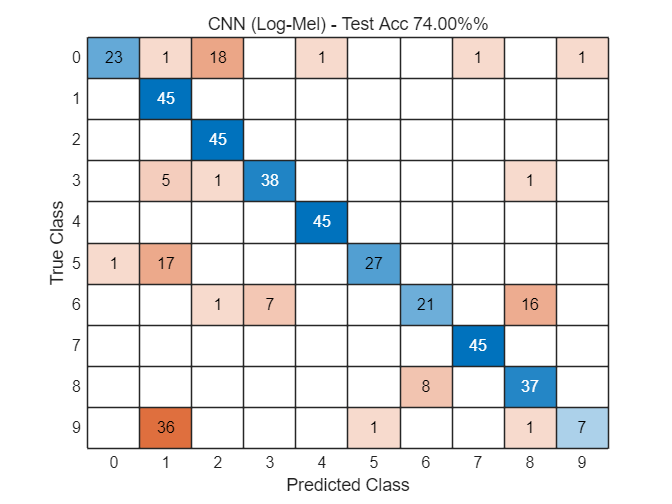


% 8.2 Confusion Matrix
figure;
confTest_cnn_clean = confusionmat(yTest_cnn, yPred_cnn_clean);     % compute confusion matrix for clean test data
confusionchart(confTest_cnn_clean, categories(yTest_cnn));
xlabel("Predicted Class");
ylabel("True Class");
title(sprintf("CNN (Log-Mel) - Test Acc %.2f%%%%", accTest_cnn*100));

%% 9. Noise robustness for both SVM and CNN

accNoisy_svm      = zeros(size(snrLevels));                     % SVM accuracy for each SNR level
accNoisy_cnn      = zeros(size(snrLevels));                     % CNN accuracy for each SNR level
latencyNoisy_cnn  = zeros(size(snrLevels));                     % CNN average latency per sample for each SNR

confNoisy_svm     = cell(size(snrLevels));                      % store SVM confusion matrix at each SNR
confNoisy_cnn     = cell(size(snrLevels));                      % store CNN confusion matrix at each SNR

for k = 1:numel(snrLevels)                                     % loop over all SNR conditions
    snr = snrLevels(k);                                        % current SNR value in dB
    fprintf("Noise test: SNR = %d dB", snr);        % header for this noise condition

% 9.1 SVM baseline: MFCC(+delta)
    [XTest_mfcc_noisy, yTest_noisy] = extractFrameFeatures( ...
        adsTest, fsTarget, ...
        "mfcc", numMFCC, useDelta, snr, ...
        frameLen, hopLen, maxTimeSec);

    [yPred_svm_noisy, accNoisy_svm(k), confNoisy_svm{k}] = ...
        evaluateClassifier(svmModel, XTest_mfcc_noisy, yTest_noisy);

    fprintf("  SVM (MFCC) accuracy %2d dB = %.2f%%%%\n", ...
        snr, accNoisy_svm(k)*100);

% 9.2 CNN: log-mel
    [XTest_cnn_noisy, yTest_cnn_noisy] = extractSpectrogramSet( ...
        adsTest, fsTarget, ...
        numMelBands, frameLen, hopLen, maxTimeSec, snr);

    tStart = tic;
    yPred_cnn_noisy = classify(net, XTest_cnn_noisy);
    tElapsed = toc(tStart);

   accNoisy_cnn(k)     = mean(yPred_cnn_noisy == yTest_cnn_noisy);      % CNN accuracy at this SNR
    confNoisy_cnn{k}    = confusionmat(yTest_cnn_noisy, yPred_cnn_noisy);      % confusion matrix for CNN
    latencyNoisy_cnn(k) = tElapsed / numel(yTest_cnn_noisy);        % average latency per sample (seconds/sample)
    fprintf("  CNN (log-mel) accuracy %2d dB = %.2f%%%%, latency = %.3f ms/sample\n", ...
        snr, accNoisy_cnn(k)*100, latencyNoisy_cnn(k)*1000);
end

Noise test: SNR = 0 dB

  SVM (MFCC) accuracy  0 dB = 10.00%%


  CNN (log-mel) accuracy  0 dB = 16.67%%, latency = 0.030 ms/sample


Noise test: SNR = 5 dB

  SVM (MFCC) accuracy  5 dB = 10.00%%


  CNN (log-mel) accuracy  5 dB = 20.44%%, latency = 0.028 ms/sample


Noise test: SNR = 10 dB

  SVM (MFCC) accuracy 10 dB = 10.00%%


  CNN (log-mel) accuracy 10 dB = 31.56%%, latency = 0.030 ms/sample


Noise test: SNR = 15 dB

  SVM (MFCC) accuracy 15 dB = 10.00%%


  CNN (log-mel) accuracy 15 dB = 45.78%%, latency = 0.029 ms/sample


Noise test: SNR = 20 dB

  SVM (MFCC) accuracy 20 dB = 10.00%%


  CNN (log-mel) accuracy 20 dB = 61.78%%, latency = 0.025 ms/sample


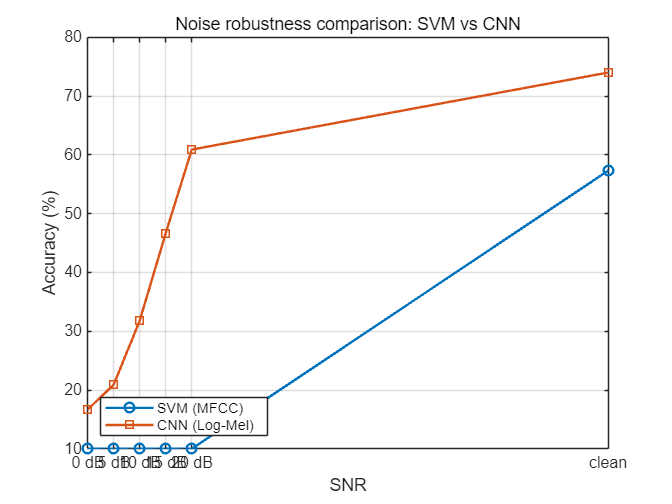

%% 10. Plot SNR vs accuracy (SVM vs CNN) 


snrAxisAcc = [snrLevels 100];    
accSvmAll  = [accNoisy_svm accTest_svm];
accCnnAll  = [accNoisy_cnn accTest_cnn];

figure;
plot(snrAxisAcc, accSvmAll*100, "-o", "LineWidth",1.5); hold on;
plot(snrAxisAcc, accCnnAll*100, "-s", "LineWidth",1.5);
grid on;

xticks(snrAxisAcc);
xticklabels([string(snrLevels)+" dB","clean"]);

xlabel("SNR");
ylabel("Accuracy (%)");
legend("SVM (MFCC)","CNN (Log-Mel)","Location","southwest");
title("Noise robustness comparison: SVM vs CNN");
hold off;

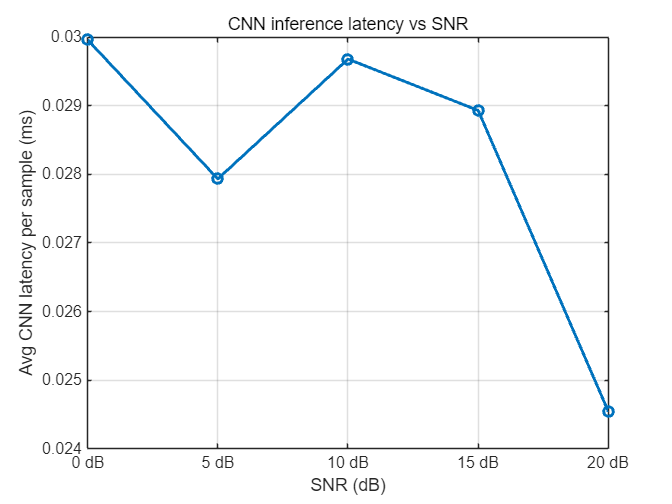

%% 11. Plot SNR vs CNN latency 

figure;
snrAxis = double(snrLevels(:));     
lat_ms   = latencyNoisy_cnn(:) * 1000;

plot(snrAxis, lat_ms, "-o", "LineWidth", 1.8, "MarkerSize", 6);
grid on;

xlabel("SNR (dB)");
ylabel("Avg CNN latency per sample (ms)");
title("CNN inference latency vs SNR");


set(gca,"XTick",snrAxis);
set(gca,"XTickLabel", string(snrAxis) + " dB");

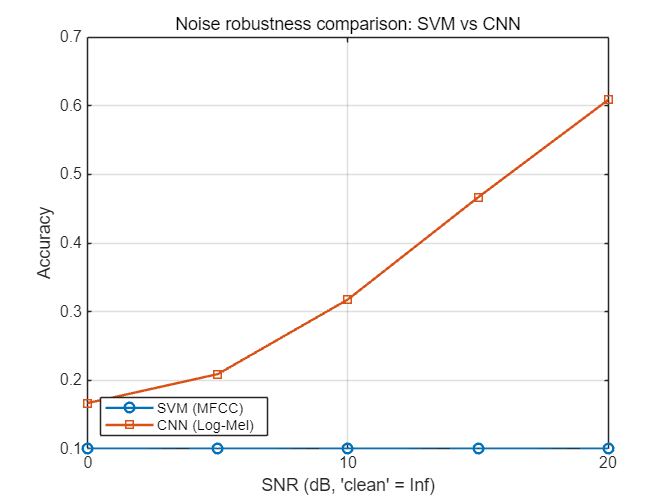

%% 12. Plot robustness comparison 

figure;
snrPlot = [Inf snrLevels];
plot(snrPlot, [accTest_svm accNoisy_svm], "-o", ...
     snrPlot, [accTest_cnn accNoisy_cnn], "-s", "LineWidth", 1.5);
xticks([0 10 20 Inf]);
xticklabels({"0","10","20","clean"});
xlabel("SNR (dB, 'clean' = Inf)");
ylabel("Accuracy");
legend("SVM (MFCC)", "CNN (Log-Mel)", "Location", "southwest");
grid on;
title("Noise robustness comparison: SVM vs CNN");

%% 13. Save everything for report 

results.fsTarget     = fsTarget;
results.accTrain_svm = accTrain_svm;
results.accVal_svm   = accVal_svm;
results.accTest_svm  = accTest_svm;
results.accTest_cnn  = accTest_cnn;
results.snrLevels    = snrLevels;
results.accNoisy_svm = accNoisy_svm;
results.accNoisy_cnn = accNoisy_cnn;
results.svmCfg       = svmCfg;

save("spoken_digit_advanced_results.mat", "-struct", "results");
fprintf("Saved results to spoken_digit_advanced_results.mat\n");

Saved results to spoken_digit_advanced_results.mat
